# Australian Temperatures

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code creates a scatter plot of the table.

data = readtable("./data/marchTemps.csv")

data = 139×3 table
    latitude    longitude    temperature
    ________    _________    ___________

      -11.4      130.42        27.347   
    -13.833      131.18        27.886   
     -14.45      132.27        30.193   
     -11.15      132.13        28.561   
     -11.65      133.38        28.393   
    -13.333      133.08        27.482   
    -13.667      134.33        27.866   
    -13.983      136.47        27.346   
    -13.767      143.12        26.289   
    -12.783       143.3        26.415   
    -14.967      145.32        26.735   
     -16.45         123         32.21   
    -18.683      121.78        33.891   
    -17.583      123.82        29.692   
    -15.517      123.15        29.393   
    -16.417       126.1        30.566   


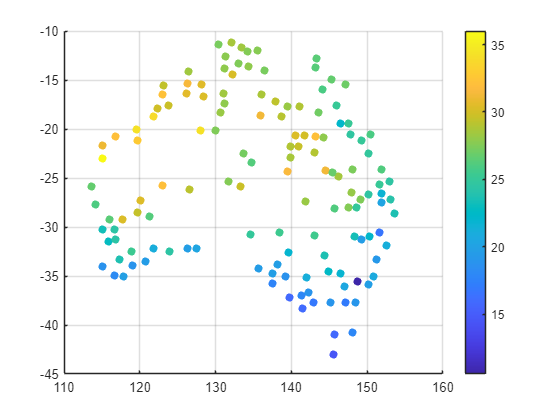

scatter(data.longitude, data.latitude, [], data.temperature, "filled")
colorbar
grid on

## Task 1

The scatter plot shows the temperature data by color for values of `lon` and `lat`.

To create outlined markers, you should use four inputs to the `scatter` function:

`scatter``(``x``,``y``,``[]``,``"k"``)`

lonnew = 120:10:150

lonnew =    120   130   140   150


latnew = [ -25 -30 -28 -32 ]

latnew =    -25   -30   -28   -32


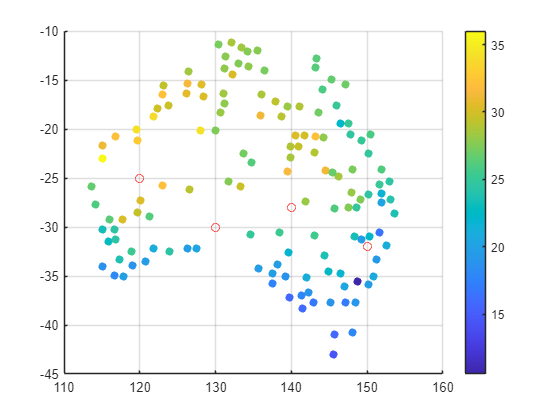

hold on
grid on
scatter(lonnew, latnew, [], "r")

## Task 2

Tnew = griddata(data.longitude, data.latitude, data.temperature, lonnew, latnew)

Tnew =    31.3230   23.2192   27.8544   19.6195


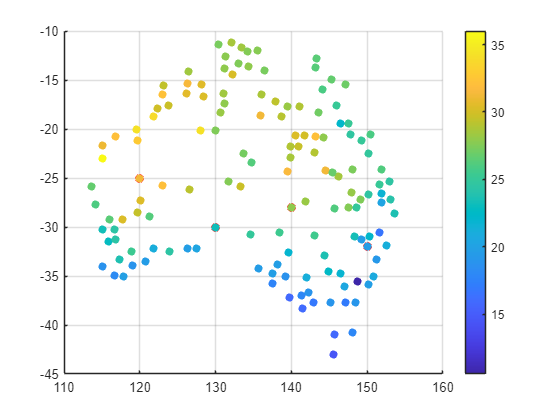

scatter(lonnew, latnew, [], Tnew, "filled")
grid on
hold off